# **Lab 7**

**Francesca Bennett**

**Collborators: Taylor Prewitt, Natalie Shen**

**Part 1**

The Higgs data from 250 to 500 is used.


$$\frac{N_{Higgs}}{\sqrt{N_{QCD}}}$$


Expected: 


$$\frac{N_{Higgs}}{\sqrt{N_{QCD}}}=\frac{50}{\sqrt{2000}}=1.118$$


Finding: 

clear all; close all; clc

%Higgs Data
h5disp("higgs_100000_pt_250_500.h5");

HDF5 higgs_100000_pt_250_500.h5 
Group '/' 
    Dataset 'higgs_100000_pt_250_500' 
        Size:  14x100000
        MaxSize:  14x100000
        Datatype:   H5T_IEEE_F64LE (double)
        ChunkSize:  []
        Filters:  none
        FillValue:  0.000000


Higgs = h5read("higgs_100000_pt_250_500.h5",'/higgs_100000_pt_250_500');

h5disp("qcd_100000_pt_250_500.h5");

HDF5 qcd_100000_pt_250_500.h5 
Group '/' 
    Dataset 'qcd_100000_pt_250_500' 
        Size:  14x100000
        MaxSize:  14x100000
        Datatype:   H5T_IEEE_F64LE (double)
        ChunkSize:  []
        Filters:  none
        FillValue:  0.000000


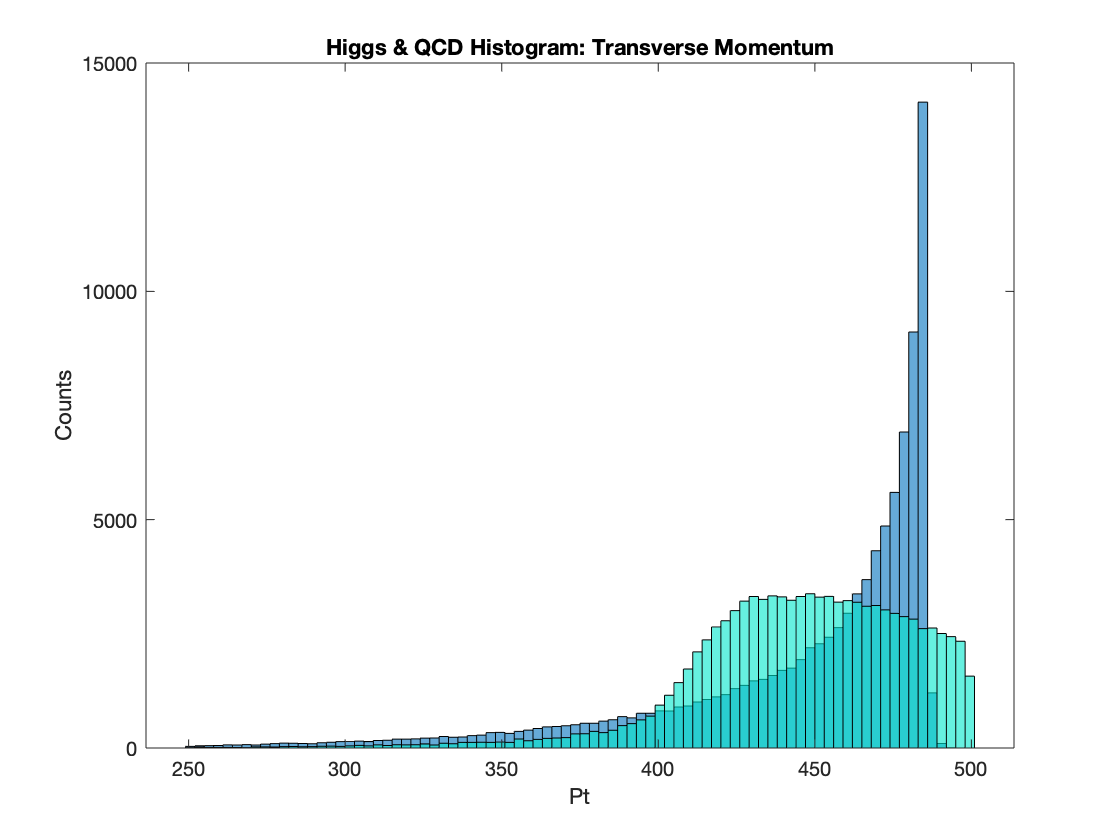

qcd = h5read("qcd_100000_pt_250_500.h5",'/qcd_100000_pt_250_500');

%Histograms of Higgs and QCD
%First: examining data for the particle transverse momentum
histogram(Higgs(1,:))
hold on
histogram(qcd(1,:),'FaceColor',"[0 0.9 0.8]")
hold off
title('Higgs & QCD Histogram: Transverse Momentum'); xlabel('Pt');
ylabel('Counts')

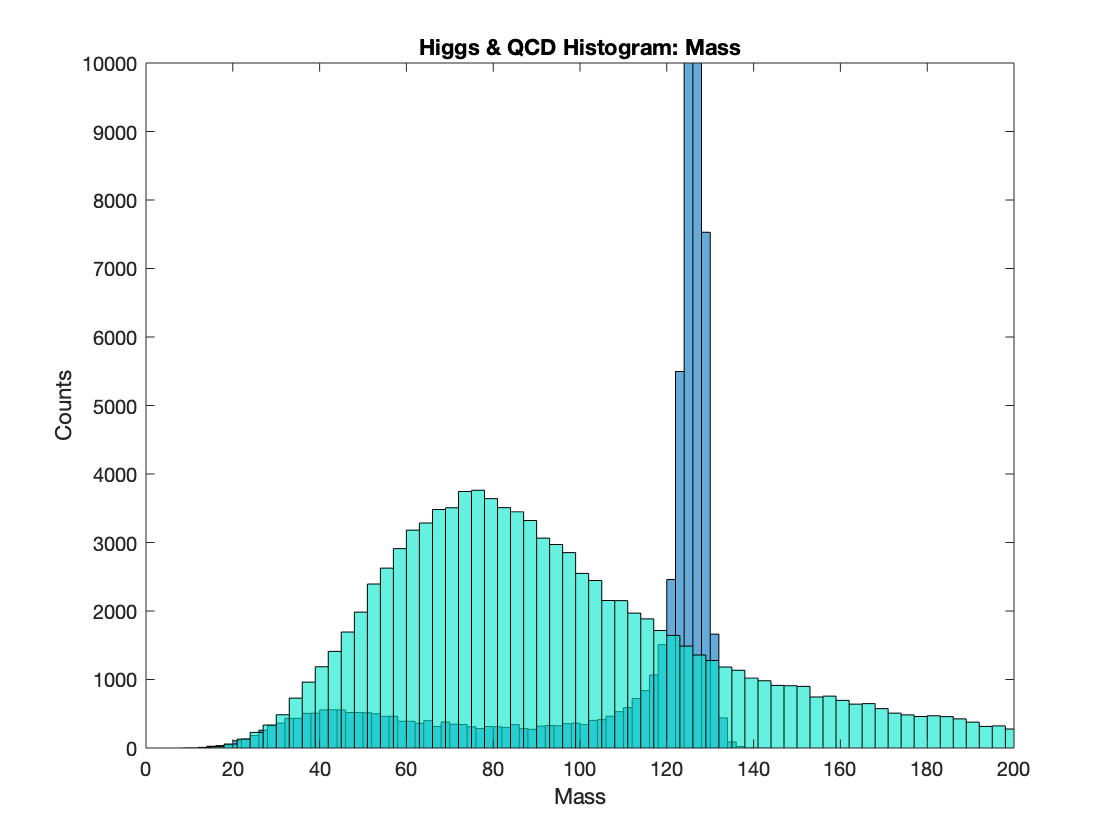


%second: examining data for the particle mass
histogram(Higgs(4,:))
hold on
histogram(qcd(4,:),'FaceColor',"[0 0.9 0.8]")
hold off
xlim([0,200])
ylim([0,10000])
title('Higgs & QCD Histogram: Mass'); xlabel('Mass')
ylabel('Counts')


%Fitting the distributions with Poisson
Hfit=fitdist(Higgs(4,:)',"Poisson");
Qfit=fitdist(qcd(4,:)',"Poisson");
Hmean=mean(Hfit);
Qmean=mean(Qfit);

%Getting the Z value for all the data
z=abs(Qmean-Hmean);

%Find the probability from the Poisson CDF of the Z values for QCD
prob=poisscdf(sqrt(length(qcd(4,:)))+z,sqrt(length(qcd(4,:))));
significance=norminv(prob)

significance = 0.9719

For a Poisson distribution,


$$P(c)=\frac{\lambda ^ce^{-\lambda }}{c!}$$


and so on.

### Part 2

Now, to narrow the data and optimize the significance of the findings, cuts are made to the data. Initially these cuts are made to the Mass for the Higgs and QCD data. 

%Scatter Plot
%Steps are used to cut back on the amount of data points
%to assist in determining patterns
scatter(Higgs(4,1:100:end),Higgs(1,1:100:end),"blue");
hold on
scatter(qcd(4,1:100:end),qcd(1,1:100:end),"cyan");
%X limit used because we want to focus on the higgs data, not the QCD
xlim([0,200])
hold on
xline(125,'--r','Linewidth',2)

ans =   ConstantLine with properties:

    InterceptAxis: 'x'
            Value: 125
            Color: [1 0 0]
        LineStyle: '--'
        LineWidth: 2
            Label: ''
      DisplayName: ''

  Show all properties


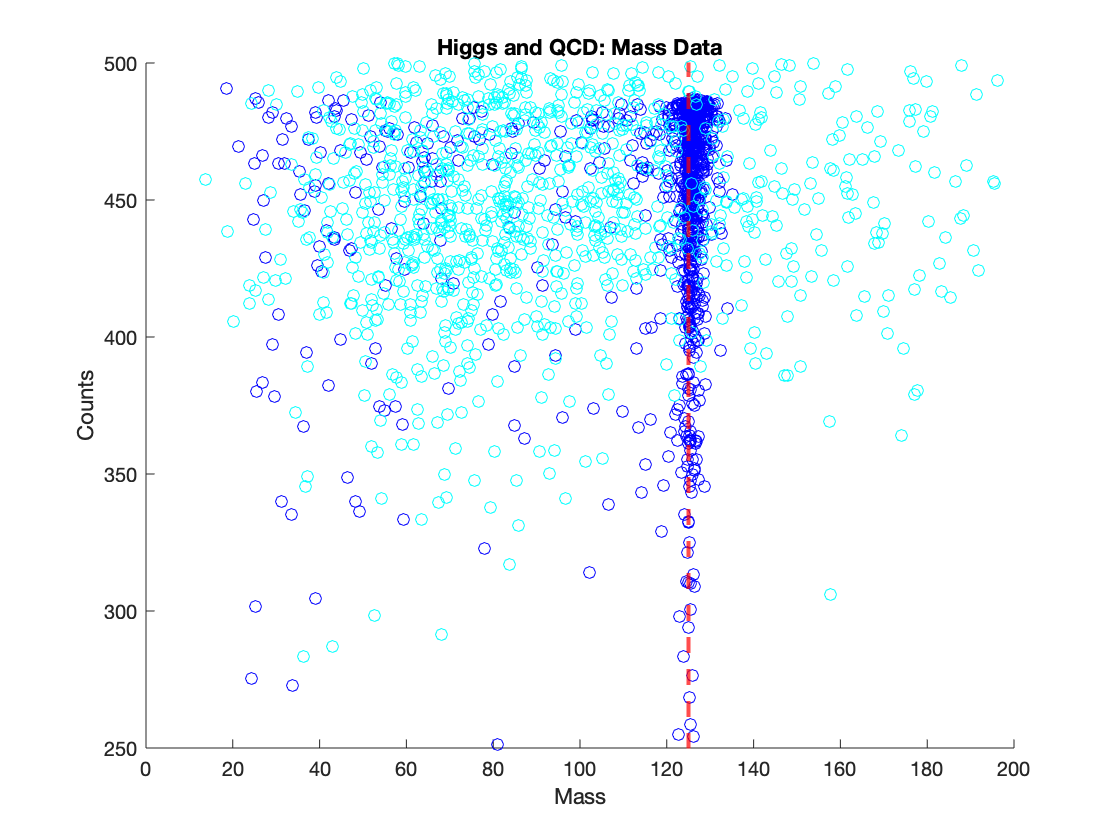

hold off
title('Higgs and QCD: Mass Data'); xlabel('Mass');ylabel('Counts')

The scatterplot comparing the Higgs and QCD masses reveals that most of the Higgs particles occur in a range less than 150, with the main conectration being at roughly 125. (At 125 counts, a red dashed line has been placed on the scatterplot.)

Cuts:

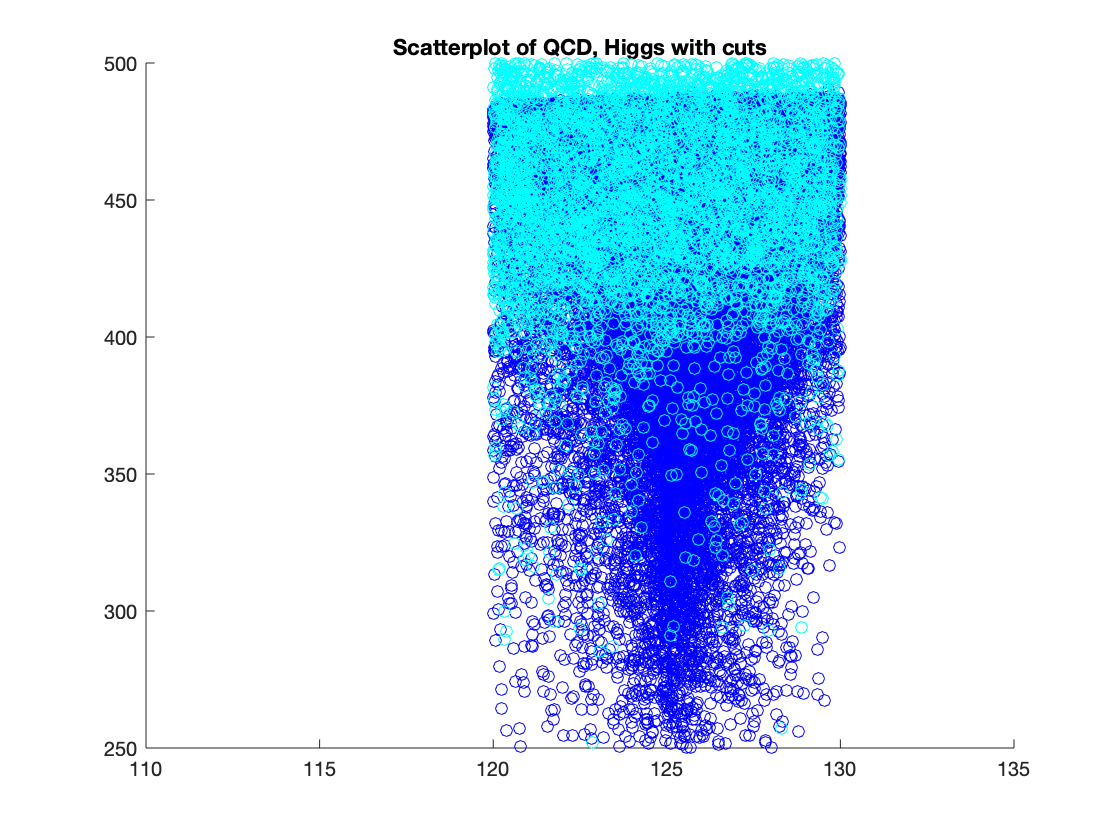

%Making cuts to the mass data
HiggsMass=Higgs(4,:);
HCut1A=HiggsMass.*(HiggsMass<130);
HCut1B=HCut1A.*(HiggsMass>120);
scatter(HCut1B,Higgs(1,:),"blue");
xlim([110,135])
hold on
QCDM=qcd(4,:);
QCut1A=QCDM.*(QCDM<130);
QCut1B=QCut1A.*(QCDM>120);
scatter(QCut1B,qcd(1,:),"cyan")
hold off
title('Scatterplot of QCD, Higgs with cuts')

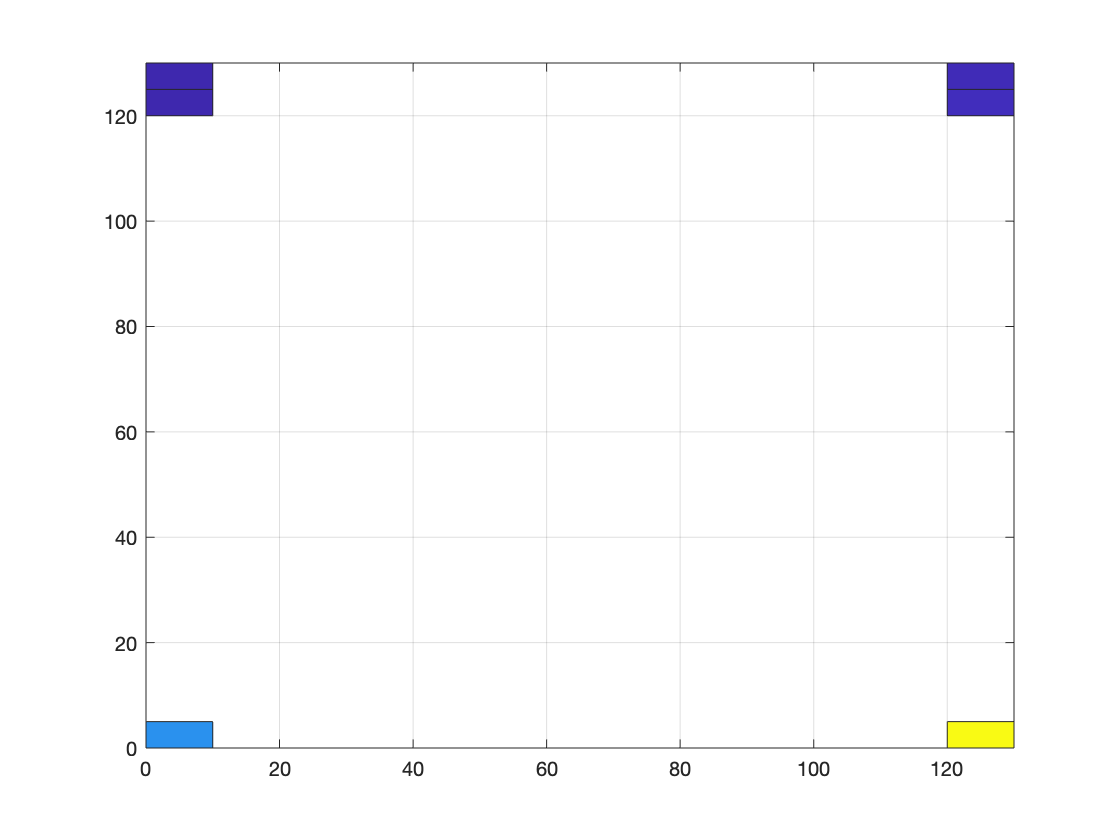


histogram2(HCut1B,QCut1B,'DisplayStyle',"tile")

After making cuts to the mass data, the expected significance for the Higgs and QCD data is related to our median events. With 2000 QCD events and 50 Higgs events as our median events, the median for total events is 2050. 




%Evaluating Significance

MeanH=mean(HCut1B);
MeanQ=mean(QCut1B);

z=abs(MeanH-MeanQ)

z = 89.2583


prob=poisscdf(sqrt(length(qcd(4,:)))+z,sqrt(length(qcd(4,:))))

prob = 1.0000


significance=norminv(prob)

significance = 4.8170

**Part 3**